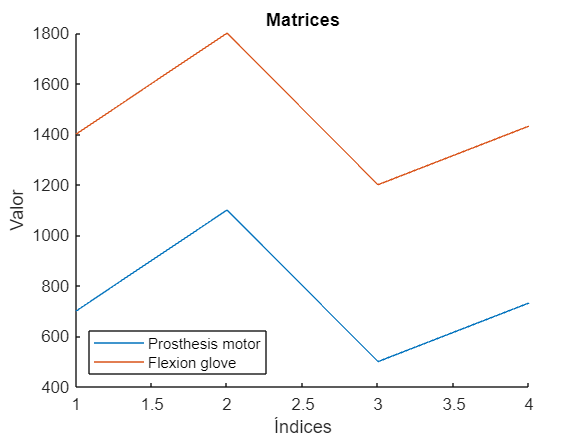

prosthesis_distance = [700, 1100, 500, 732];
glove_distance = [1400, 1800, 1200, 1432];
% prosthesis_distance = [1400, 1800, 1400, 1000];
% glove_distance = [1400, 1000, 1400, 1800];
[n, ~] = size(prosthesis_distance);
prosthesis_distance_distance = prosthesis_distance((n):n, :);
[n, ~] = size(glove_distance);
glove_distance_distance = glove_distance((n):n, :);
aux_1 = prosthesis_distance_distance;
aux_2 = glove_distance_distance;
prosthesis_distance = cat(1, aux_1(:));
glove_distance = cat(1, aux_2(:));
f = figure(1);
ax = subplot(1, 1, 1, "Parent", f);
cla(ax);
hold(ax, "on");
plot(ax, prosthesis_distance(:, 1));
plot(ax, glove_distance(:, 1));
legend(ax, sprintf("Prosthesis motor"), "Flexion glove", "Location","southwest")
title(ax, sprintf("Matrices"))
legend(ax, 'Prosthesis motor', 'Flexion glove');
xlabel(ax, 'Índices');
ylabel(ax, 'Valor');

% xlabel(ax, num2str(max_diferencia))
drawnow
% Inicializar la sumatoria de diferencias
sumatoria_diferencias = 0;
% Comparar los valores de 1 en 1 y obtener la sumatoria de las diferencias
for i = 1:4
    diferencia = abs(prosthesis_distance(i) - glove_distance(i));
    sumatoria_diferencias = sumatoria_diferencias + diferencia;
    fprintf('La diferencia %d es: %s\n', i, num2str(diferencia));
end

La diferencia 1 es: 700
La diferencia 2 es: 700
La diferencia 3 es: 700
La diferencia 4 es: 700


% Mostrar el resultado global
disp(['La sumatoria global de las diferencias es:', num2str(-1*sumatoria_diferencias)]);

La sumatoria global de las diferencias es:-2800
